# Deep Leraning - Deep Neural Network

clc; close all; clear all;


## 1.Data reading

[data, datatxt,dataraw] = xlsread("test.xlsx");
[m n] = size(data);


### 2. Data Normalization and Categorization 

maxValue = max(max(data));
data = data./maxValue;

trainingPortion = 0.8;
rIndex = randperm(m)';
trainIndex = floor(m.*trainingPortion);

trainingData = data(rIndex(1:trainIndex),:);
testData = data(rIndex(trainIndex+1:m),:);

xTrain = trainingData(:,1:10);
yTrain = trainingData(:,11);

xTest = testData(:,1:10);
yTest = testData(:,11);


### 3. Data Analysis

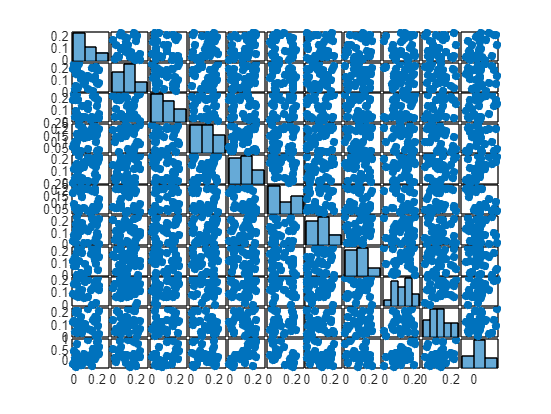


figure(1);
gplotmatrix(data);

4. Architecture of Deep Learning

layers = [
    featureInputLayer(10,"Name","featureinput")
    fullyConnectedLayer(20,"Name","fc_1")
    tanhLayer("Name","tanh_1")
    fullyConnectedLayer(15,"Name","fc_3")
    tanhLayer("Name","tanh_3")
    fullyConnectedLayer(10,"Name","fc_2")
    tanhLayer("Name","tanh_2")
    fullyConnectedLayer(7,"Name","fc_4")
    tanhLayer("Name","tanh_4")
    fullyConnectedLayer(3,"Name","fc_5")
    tanhLayer("Name","tanh_5")
    fullyConnectedLayer(2,"Name","fc_6")
    tanhLayer("Name","tanh_6")
    fullyConnectedLayer(1,"Name","fc_7")
    regressionLayer("Name","regressionoutput")];


## 5. Training Options

options = trainingOptions("adam", ...
    MaxEpochs=500, ...
    InitialLearnRate=0.01,...
    Plots="training-progress");


### 6. Deep Learning

단일 CPU에서 훈련합니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　ＲＭＳＥ　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０１　｜　　　　　　　　　０．３４　｜　　　　５．９ｅ－０２　｜　　　０．０１００　｜
｜　　　　　　５０　｜　　　　　　５０　｜　　　　　００：００：０１　｜　　　　　　　　　０．０４　｜　　　　６．７ｅ－０４　｜　　　０．０１００　｜
｜　　　　　１００　｜　　　　　１００　｜　　　　　００：００：０２　｜　　　　　　　　　０．０１　｜　　　　９．０ｅ－０５　｜　　　０．０１００　｜
｜　　　　　１５０　｜　　　　　１５０　｜　　　　　００：００：０３　｜　　　　　　　　　０．０１　｜　　　　５．５ｅ－０５　｜　　　０．０１００　｜
｜　　　　　２００　｜　　　　　２００　｜　　　　　００：００：０３　｜　　　　　　　　　０．０１　｜　　　　７．６ｅ－０５　｜　　　０．０１００　｜
｜　　　　　２５０　｜　　　　　２５０　｜　　　　　００：００：０４　｜　　　　　９．３０ｅ－０３　｜　　　　４．３ｅ－０５　｜　　　０．０１００　｜
｜　　　　　３００　｜　　　　　３００　｜　　　　　００：００：０４　｜　　　　　８．５２ｅ－０３　｜　　　　３．６ｅ－０５　｜　　　０．０１００　｜
｜　　　　　３５０　｜　　　　　３５０　｜　　　　　００：００：０５　｜　　　　　　　　　０．０１　｜　　　　９．８ｅ－０５　｜　　　０．０１００　｜
｜　　　　　４００　｜　　　　　４００　｜　　　　　００：００：０５　｜　　　　　８．９１ｅ－０３　｜　　　　４．０ｅ－０５　｜　　　０．０１０

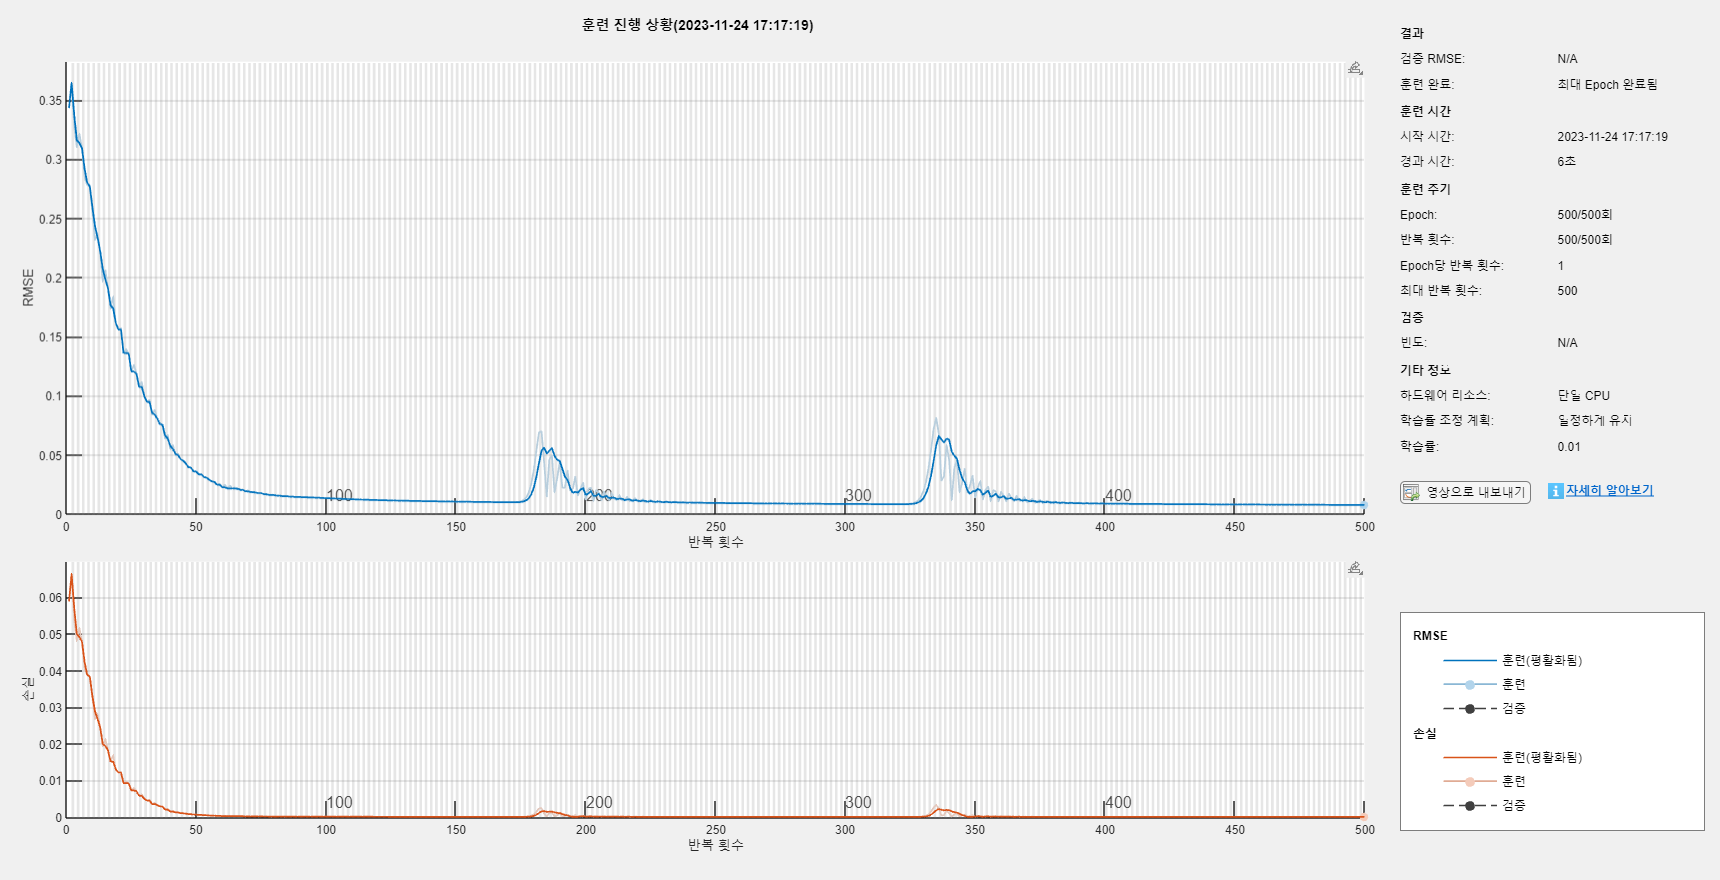


[net, info] = trainNetwork(xTrain,yTrain,layers,options);

## 7. Validation

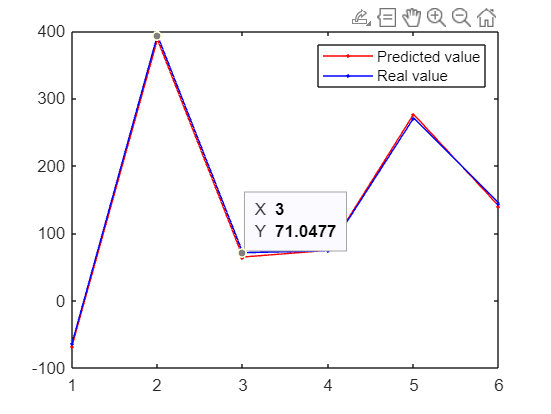

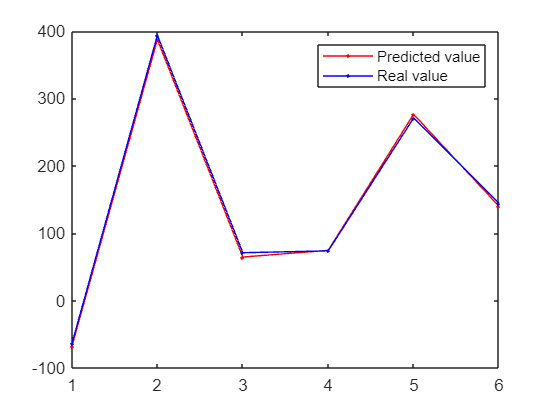

yPredict = predict(net,xTest);
yPredict = yPredict.*maxValue;
yTest = yTest.*maxValue;

figure(3);
set(gcf,'color',[1 1 1]);
plot(yPredict,'r.-');
hold on;
plot(yTest,'b.-');
hold off;
legend('Predicted value','Real value');

## 8. Prediction


% realX = [1,34, ...]
% y = predict(net,realX);











